# Overview

Given the output of a Revopoint structured-light 3D scan, this procedure outlines the steps in localizing the EEG channels, HPI coils, fiducials, and extra head points and then importing this channel information and the rendered head surface mesh into Brainstorm.

The two localization procedures we are using with the Revopoint scan are **FieldTrip's "3D rendered mesh localization procedure"** and a "**2D projection surface of the mesh" localization procedure**. The steps for each are as follows:

### FieldTrip 3D Rendered Mesh Localization Procedure

- Read the OBJ file for the surface mesh.

- Convert the units of the mesh.

- Localize the fiducials of the head surface.

- Realign the mesh on the bases of the fiducials to CTF coordinates.

- Localize the electrode locations on a 3D rendered mesh. (Optionally: Localize the HPI coils on a 3D rendered mesh.)

- Convert the head surface and electrode location structure into Brainstorm compatible MATLAB structures.

- Derive the fiducial positions relative to the CTF coordinate system.

- Add fiducials into the electrode location Brainstorm MATLAB structure. (Optionally: Add HPI coils into the electrode location Brainstorm MATLAB structure.)

- Save the Brainstorm structures in a local folder.

- Import the Brainstorm structures into Brainstorm.

### 2D Projection Localization Procedure

- Read the OBJ file for the surface mesh.

- Convert the units of the mesh.

- Localize the fiducials of the head surface.

- Realign the mesh on the bases of the fiducials to CTF coordinates.

- Localize the electrode locations on a 2D projected surface of the mesh. (Optionally: Localize the HPI coils on a 2D projected surface of the mesh.)

- Convert the head surface and electrode location structure into Brainstorm compatible MATLAB structures.

- Derive the fiducial positions relative to the CTF coordinate system.

- Add fiducials into the electrode location Brainstorm MATLAB structure. (Optionally: Add HPI coils into the electrode location Brainstorm MATLAB structure.)

- Save the Brainstorm structures in a local folder.

- Import the Brainstorm structures into Brainstorm.

## Directory Folders

- *cap_specifications*: Folder of '.mat' files containing labels for caps of size **32** [EEG Cap 32 channels based on CA-065 identical CW-0434, 10/20 (Code: CW-3484)], **64** [EEG cap, 64 ch, identical to CW-0435, 10/10 (Code: CW-3485)], **128 **[waveguard original cap, 128 channels with 5 HPI coil openings, 10/5, unshielded, Redel connector], **256** [EEG dry cap, 256 channels, shielded, equidistant, Tyco68 (Code: CY-281.s1)].

- *eeg_cap_documentation*: PDF documents outlining the template cap layouts for caps of sizes **32**, **64**, **128**, and **256**.

- *revopoint_scan*: Folder containing the OBJ, MTL, and JPG Revopoint scan output for the example used in the procedural steps below.

- *generated_structures*: Folder where the resulting Brainstorm output structures (from running the procedure) will be stored as '.mat' files.

- *channel_layouts*: Folder of PNG image files containing the template cap layout for caps of sizes **32**, **64**, and **128**.

## Software dependencies

- FieldTrip Toolbox: Download FieldTrip Toolbox for MATLAB

- Brainstorm: Download Brainstorm for MATLAB

## Demo Script Note

- Intermediate resulting structures for each of the steps are stored in the file path '.../generated_structures/demo_structures'.

## Step 1: Read the OBJ file for the surface mesh structure

clc;clear all;close all;restoredefaultpath;

% filepath = '../../stimCap/OBJ/model-2022-10-19-15-45-47_mesh_tex.obj';
addpath('/home/ajoshi/Projects/3Dscanner2Brainstorm/dev/fieldtrip-20240424');
ft_defaults

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re


%filepath = '/home/ajoshi/Projects/3Dscanner2Brainstorm/data/send_to_joshi/revopoint_samples/yash-64ch-Obj_mesh_tex.obj';
filepath = '/home/ajoshi/Downloads/EEG-caps-objs/ant256-s3-t3obj_mesh_tex.obj'

filepath = '/home/ajoshi/Downloads/EEG-caps-objs/ant256-s3-t3obj_mesh_tex.obj'

head_surface = import_obj(filepath, 'meshed');

## Step 2: Convert the units of the mesh

%load ./generated_structures/demo_structures/step_1/head_surface.mat
head_surface = ft_convert_units(head_surface, 'mm');

## Step 3: Localize the fiducials of the head surface

The axes are 150 mm long in each direction
The diameter of the sphere at the origin is 10 mm
The coordinate system is not specified.


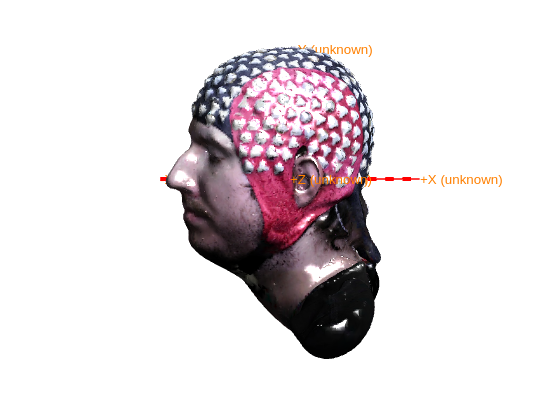

0. Press "h" to show this help
1. Options for electrode placement:
   a. Use the mouse to click on the desired position for an electrode
   b. Click on the corresponding electrode label
   c. Double-click on an electrode label to remove the marker
2. Press "v" to update the light position
3. Press "q" or close the window when you are done
the call to "ft_electrodeplacement" took 161 seconds and required the additional allocation of an estimated 0 MB


%load ./generated_structures/demo_structures/step_2/head_surface.mat
cfg = [];
cfg.method = 'headshape';
fiducials = ft_electrodeplacement(cfg, head_surface);

% Prompt: "Do you want to change the anatomical labels for the axes [Y, n]?"
% Prompt Response: n

% Localization Procedure of the Fiducials
%   1. Enable rotate/zoom.
%   2. Rotate/zoom the 3D mesh.
%   3. Disable rotate/zoom.
%   4. Select the anatomical landmark.
%   5. Select the fiducial label.
%       a. "1" for the first fiducial. (NPA)
%       b. "2" for the second fiducial. (LPA)
%       c. "3" for the third fiducial. (RPA)
%   6. Repeat
%   7. When complete, press 'q'.

## Step 4: Realign the mesh on the basis of the fiducials to CTF coordinates

%load ./generated_structures/demo_structures/step_3/fiducials.mat
cfg = [];
cfg.method        = 'fiducial';
cfg.coordsys      = 'ctf';
cfg.fiducial.nas  = fiducials.elecpos(1,:); %NAS
cfg.fiducial.lpa  = fiducials.elecpos(2,:); %LPA
cfg.fiducial.rpa  = fiducials.elecpos(3,:); %RPA
head_surface = ft_meshrealign(cfg, head_surface);

the input is mesh data with 78736 vertices and 157472 triangles
the input is source data with 78736 brainordinates
the call to "ft_meshrealign" took 0 seconds and required the additional allocation of an estimated 0 MB


# Step 5: FieldTrip Localization Procedure

- Note: This section regarding Step 5 only relates to the FieldTrip Localization Procedure for electrode localization and the HPI coil localization. Note that section titled "Step 5: 2D Projection Localization Procedure" relates to the same steps but for the 2D Projection Localization Procedure. If you are only interested in one procedure, run its corresponding Step 5 section (depending on the procedure of interest).

## Step 5: Localize the electrode locations on a 3D rendered mesh

%load ./generated_structures/demo_structures/step_4/head_surface.mat
% Displays channel layout of supported 64ch
[image, cmap] = imread('./channel_layouts/waveguard_layout_064ch.png');
set(gcf, 'Visible', 'on');
imshow(image, cmap);

cfg = [];
cfg.method = 'headshape';
elec = ft_electrodeplacement(cfg, head_surface);

% Localization Procedure of the Electrode Channels
%   1. Enable rotate/zoom.
%   2. Rotate/zoom the 3D mesh.
%   3. Disable rotate/zoom.
%   4. Select the electrode channel landmark.
%   5. Select the electrode label.
%       a. Follow cap layout template ordering.
%   6. Repeat
%   7. When complete, press 'q'.

%   Supported cap layout templates: Cap Layout Template Files (Relavtive
%   Path: 'cap_specifications\...')
%       1. 32:  EEG Cap 32 channels based on CA-065 identical CW-0434,
%               10/20
%               (Code: CW-3484)
%       2. 64:  EEG cap, 64 ch, identical to CW-0435, 10/10
%               (Code: CW-3485)
%       3. 128: waveguard original cap, 128 channels with 5 HPI coil
%               openings, 10/5, unshielded, Redel connector 
%               (Code: CA-069.s1)
%       4. 256: EEG dry cap, 256 channels, shielded, equidistant, Tyco68
%               (Code: CY-281.s1)

## Step 5a: Localize the HPI coil locations on a 3D rendered mesh

cfg = [];
cfg.method = 'headshape';
hpi = ft_electrodeplacement(cfg, head_surface);

% Localization Procedure of the HPI coils
%   1. Enable rotate/zoom.
%   2. Rotate/zoom the 3D mesh.
%   3. Disable rotate/zoom.
%   4. Select the HPI coil landmark.
%   5. Select the HPI coil label.
%       a. Follow cap layout template ordering for HPI coils.
%   6. Repeat
%   7. When complete, press 'q'.

% NOTE:
%   EEG dry cap, 256 channels, shielded, equidistant, Tyco68 (Code: CY-281.s1)
%   does not have any HPI coils. No need to do this step for this 256 channel
%   cap.

# Step 5: 2D Projection Localization Procedure

- Note: This section regarding Step 5 only relates to the 2D Projection Localization Procedure for electrode localization and the HPI coil localization. Note that section titled "Step 5: FieldTrip Localization Procedure" relates to the same steps but for the FieldTrip Localization Procedure. If you are only interested in one procedure, run its corresponding Step 5 section (depending on the procedure of interest).

## Step 5: Localize the electrode locations on a 2D projected surface of the mesh

% Displays channel layout of supported 64ch
[image, cmap] = imread('./channel_layouts/waveguard_layout_064ch.png');
set(gcf, 'Visible', 'on');
imshow(image, cmap);

% Number of positions (electrodes) to localize.
numLoc = 64;

hs = mesh_project_2d(head_surface);
set(gcf, 'Visible', 'on');
elec = projection_electrodeplacement(hs, numLoc);

% Localization Procedure of the Electrode Channels
%   1. Zoom.
%   2. Press any key to disable zoom.
%   3. Select the electrode landmark.
%   4. Repeat.
%       a. Follow cap layout template ordering.

%   Supported cap layout templates:
%       1. 32:  EEG Cap 32 channels based on CA-065 identical CW-0434,
%               10/20
%               (Code: CW-3484)
%       2. 64:  EEG cap, 64 ch, identical to CW-0435, 10/10
%               (Code: CW-3485)
%       3. 128: waveguard original cap, 128 channels with 5 HPI coil
%               openings, 10/5, unshielded, Redel connector 
%               (Code: CA-069.s1)
%       4. 256: EEG dry cap, 256 channels, shielded, equidistant, Tyco68
%               (Code: CY-281.s1)

## Step 5a (Optional): Localize the HPI coil locations on a 2D projected surface of the mesh

% Number of positions (HPI coils) to localize.
numLoc = 5;

hs = mesh_project_2d(head_surface);
set(gcf, 'Visible', 'on');
hpi = projection_electrodeplacement(hs, numLoc);

% Localization Procedure of the Electrode Channels
%   1. Zoom.
%   2. Press any key to disable zoom.
%   3. Select the HPI coil landmark.
%   4. Repeat.
%       a. Follow cap layout template ordering for HPI coils.

% NOTE:
%   EEG dry cap, 256 channels, shielded, equidistant, Tyco68 (Code: CY-281.s1)
%   does not have any HPI coils. No need to do this step for this 256 channel
%   cap.

## Step 6: Convert the head surface and electrode location structures into Brainstorm compatible MATLAB structures

load ./generated_structures/demo_structures/step_5/elec.mat
load ./generated_structures/demo_structures/step_5/hpi.mat
% Electrode Location Structure
% Number of electrode channels localized.
numChannel = 64;
channelMat = elec_to_channelMat(elec, numChannel);

% Head Surface
bs_head_surface = head_surface_conversion(head_surface);

## Step 7: Derive the fiducial positions relative to the CTF coordinate system

load ./generated_structures/demo_structures/step_6/bs_head_surface.mat
load ./generated_structures/demo_structures/step_6/channelMat.mat
[transform, ~] = ft_headcoordinates(fiducials.elecpos(1,:), fiducials.elecpos(2,:), fiducials.elecpos(3,:), 'ctf');
fid = [];
fid.elecpos = fiducials.elecpos;
fid = ft_transform_geometry(transform, fid);

## Step 8: Add fiducials into the electrode location Brainstorm MATLAB structure

load ./generated_structures/demo_structures/step_7/fid.mat
channelMat = add_fiducials(fid, channelMat);

## Step 8a (Optional): Add HPI coils into the electrode location Brainstorm MATLAB structure

channelMat = add_hpis(hpi, channelMat);

# Save the Brainstorm structures

save('generated_structures\bs_head_surface.mat', 'bs_head_surface');
save('generated_structures\channelMat.mat', 'channelMat');

# Import into Brainstorm

## Import Head Surface

- Switch to the Anatomy view tab.

- Duplicate **head surface**

- Right-click on duplicated **head surface** > File > **Import from MATLAB**

- Select the workspace variable of the Brainstorm head surface structure (`bs_head_surface`) > **OK**

## Import EEG Channel Positions

- Switch to the Functional view tab.

- Right-click on channel file > File > **Import from MATLAB**

- Select the workspace variable of the Brainstorm head surface structure (`channelMat`) > **OK**

# Optional Steps

## A: Adding additional headpoints of the surface

- Before: "Adding additional headpoints of the surface" steps should be done after importing the structures from the procedure above.

Decimate Head Surface

- Switch to the Anatomy view tab.

- Right-click on **revopoint head surface** > Less vertices…

- Resample to desired number of extra headpoints.

- Select desired sampling method. (Recommended: MATLAB’s reducepatch)

Export head surface to MATLAB

- Right-click on decimated version of the **revopoint head surface** > File > **Export to MATLAB**

- Enter a name for the Brainstorm head surface structure > **OK**

Export channel locations to MATLAB

- Switch to the Functional view tab.

- Right-click on channel file > File > **Export to MATLAB**

- Enter a name for the Brainstorm channel location structure > **OK**

Add the EXTRA points

- Add the additional head points to the channel location structure.

channelMat = add_extra_points(bs_head_surface, bs_channelMat);

Import EEG Channel Position Structure into Brainstorm

- Import EEG channel position structure `channelMat `into Brainstorm.